## Collect file paths to the data files

The output of *getFileNames* is a string array containing the required file paths.

LGWFiles = getFileNames("Processed Data\IMU Data for assignment\LGW");
RAFiles = getFileNames("Processed Data\IMU Data for assignment\Ramp ascend");
RDFiles = getFileNames("Processed Data\IMU Data for assignment\Ramp descend");
SiStFiles = getFileNames("Processed Data\IMU Data for assignment\Sit to stand");
StSiFiles = getFileNames("Processed Data\IMU Data for assignment\Stand to sit");

## Read and collect the data

*collectData* takes the list of file paths given by *getFileNames* as input and outputs a struct of tables containing the data of all the files. The struct field name is the name of the file and the corresponding value contains the data from that file.

LGWRaw = collectData(LGWFiles);
RARaw = collectData(RAFiles);
RDRaw = collectData(RDFiles);
SiStRaw = collectData(SiStFiles);
StSiRaw = collectData(StSiFiles);
clearvars LGWFiles RAFiles RDFiles SiStFiles StSiFiles

## Check unnecessary extra columns

% Check column count
printColCount(LGWRaw)

normal_walk_J_trial_01 has 72 columns.
normal_walk_J_trial_02 has 72 columns.
normal_walk_J_trial_03 has 72 columns.
normal_walk_SV_trial_01 has 78 columns.
normal_walk_SV_trial_02 has 78 columns.
normal_walk_SV_trial_03 has 78 columns.
normal_walk_lg_trial_01 has 74 columns.
normal_walk_lg_trial_02 has 74 columns.
normal_walk_lg_trial_03 has 74 columns.
normal_walk_vr_trial_01 has 74 columns.
normal_walk_vr_trial_02 has 74 columns.
normal_walk_vr_trial_03 has 74 columns.


printColCount(RARaw)

ramp_asc_vr_trial_03 has 74 columns.
ramp_asc_j_trial_01 has 74 columns.
ramp_asc_j_trial_02 has 74 columns.
ramp_asc_j_trial_03 has 74 columns.
ramp_asc_lg_trial_01 has 74 columns.
ramp_asc_lg_trial_02 has 74 columns.
ramp_asc_lg_trial_03 has 74 columns.
ramp_asc_rs_trial_01 has 74 columns.
ramp_asc_rs_trial_02 has 74 columns.
ramp_asc_rs_trial_03 has 74 columns.
ramp_asc_vr_trial_01 has 74 columns.
ramp_asc_vr_trial_02 has 74 columns.


printColCount(RDRaw)

ramp_desc_jun_trial_01 has 74 columns.
ramp_desc_jun_trial_02 has 74 columns.
ramp_desc_jun_trial_03 has 74 columns.
ramp_desc_lg_trial_01 has 74 columns.
ramp_desc_lg_trial_02 has 74 columns.
ramp_desc_lg_trial_03 has 74 columns.
ramp_desc_rs_trial_01 has 74 columns.
ramp_desc_rs_trial_02 has 74 columns.
ramp_desc_rs_trial_03 has 74 columns.
ramp_desc_vr_trial_01 has 74 columns.
ramp_desc_vr_trial_02 has 74 columns.
ramp_desc_vr_trial_03 has 74 columns.


printColCount(SiStRaw)

sit_to_stand_jun_trial_01 has 74 columns.
sit_to_stand_jun_trial_02 has 74 columns.
sit_to_stand_jun_trial_03 has 74 columns.
sit_to_stand_lg_trial_01 has 74 columns.
sit_to_stand_lg_trial_02 has 74 columns.
sit_to_stand_lg_trial_03 has 74 columns.
sit_to_stand_rs_trial_01 has 74 columns.
sit_to_stand_rs_trial_02 has 74 columns.
sit_to_stand_rs_trial_03 has 74 columns.
sit_to_stand_vr_trial_01 has 74 columns.
sit_to_stand_vr_trial_02 has 74 columns.
sit_to_stand_vr_trial_03 has 74 columns.


printColCount(StSiRaw)

Students_stand_to_sit_lg_trial_01 has 74 columns.
Students_stand_to_sit_lg_trial_02 has 74 columns.
Students_stand_to_sit_lg_trial_03 has 74 columns.
Students_stand_to_sit_vr_trial_01 has 74 columns.
Students_stand_to_sit_vr_trial_02 has 74 columns.
Students_stand_to_sit_vr_trial_03 has 74 columns.
stand_to_sit_j_trial_01 has 74 columns.
stand_to_sit_j_trial_02 has 74 columns.
stand_to_sit_j_trial_03 has 74 columns.
stand_to_sit_rs_trial_01 has 74 columns.
stand_to_sit_rs_trial_02 has 74 columns.
stand_to_sit_rs_trial_03 has 74 columns.



% Check extra columns
printExtraCols(LGWRaw)

Extra column names (4 exist) in normal_walk_J_trial_01 are:
Foot_R_Timestamp, Shank_R_Timestamp, Thigh_L_Timestamp, Thigh_R_Timestamp, 

Extra column names (4 exist) in normal_walk_J_trial_02 are:
Foot_R_Timestamp, Shank_R_Timestamp, Thigh_L_Timestamp, Thigh_R_Timestamp, 

Extra column names (4 exist) in normal_walk_J_trial_03 are:
Foot_R_Timestamp, Shank_R_Timestamp, Thigh_L_Timestamp, Thigh_R_Timestamp, 

Extra column names (10 exist) in normal_walk_SV_trial_01 are:
Foot_L_Offset_Timestamp, Foot_L_Sync_Timestamp, Foot_R_Sync_Timestamp, Pelvis_Offset_Timestamp, Pelvis_Sync_Timestamp, Shank_L_Offset_Timestamp, Shank_L_Sync_Timestamp, Shank_R_Sync_Timestamp, Thigh_L_Sync_Timestamp, Thigh_R_Sync_Timestamp, 

Extra column names (10 exist) in normal_walk_SV_trial_02 are:
Foot_L_Offset_Timestamp, Foot_L_Sync_Timestamp, Foot_R_Sync_Timestamp, Pelvis_Offset_Timestamp, Pelvis_Sync_Timestamp, Shank_L_Offset_Timestamp, Shank_L_Sync_Timestamp, Shank_R_Sync_Timestamp, Thigh_L_Sync_Timestamp, Thigh

printExtraCols(RARaw)

Extra column names (0 exist) in ramp_asc_vr_trial_03 are:
, 

Extra column names (0 exist) in ramp_asc_j_trial_01 are:
, 

Extra column names (0 exist) in ramp_asc_j_trial_02 are:
, 

Extra column names (0 exist) in ramp_asc_j_trial_03 are:
, 

Extra column names (0 exist) in ramp_asc_lg_trial_01 are:
, 

Extra column names (0 exist) in ramp_asc_lg_trial_02 are:
, 

Extra column names (0 exist) in ramp_asc_lg_trial_03 are:
, 

Extra column names (0 exist) in ramp_asc_rs_trial_01 are:
, 

Extra column names (0 exist) in ramp_asc_rs_trial_02 are:
, 

Extra column names (0 exist) in ramp_asc_rs_trial_03 are:
, 

Extra column names (0 exist) in ramp_asc_vr_trial_01 are:
, 

Extra column names (0 exist) in ramp_asc_vr_trial_02 are:
, 



printExtraCols(RDRaw)

Extra column names (0 exist) in ramp_desc_jun_trial_01 are:
, 

Extra column names (0 exist) in ramp_desc_jun_trial_02 are:
, 

Extra column names (0 exist) in ramp_desc_jun_trial_03 are:
, 

Extra column names (0 exist) in ramp_desc_lg_trial_01 are:
, 

Extra column names (0 exist) in ramp_desc_lg_trial_02 are:
, 

Extra column names (0 exist) in ramp_desc_lg_trial_03 are:
, 

Extra column names (0 exist) in ramp_desc_rs_trial_01 are:
, 

Extra column names (0 exist) in ramp_desc_rs_trial_02 are:
, 

Extra column names (0 exist) in ramp_desc_rs_trial_03 are:
, 

Extra column names (0 exist) in ramp_desc_vr_trial_01 are:
, 

Extra column names (0 exist) in ramp_desc_vr_trial_02 are:
, 

Extra column names (0 exist) in ramp_desc_vr_trial_03 are:
, 



printExtraCols(SiStRaw)

Extra column names (0 exist) in sit_to_stand_jun_trial_01 are:
, 

Extra column names (0 exist) in sit_to_stand_jun_trial_02 are:
, 

Extra column names (0 exist) in sit_to_stand_jun_trial_03 are:
, 

Extra column names (0 exist) in sit_to_stand_lg_trial_01 are:
, 

Extra column names (0 exist) in sit_to_stand_lg_trial_02 are:
, 

Extra column names (0 exist) in sit_to_stand_lg_trial_03 are:
, 

Extra column names (0 exist) in sit_to_stand_rs_trial_01 are:
, 

Extra column names (0 exist) in sit_to_stand_rs_trial_02 are:
, 

Extra column names (0 exist) in sit_to_stand_rs_trial_03 are:
, 

Extra column names (0 exist) in sit_to_stand_vr_trial_01 are:
, 

Extra column names (0 exist) in sit_to_stand_vr_trial_02 are:
, 

Extra column names (0 exist) in sit_to_stand_vr_trial_03 are:
, 



printExtraCols(StSiRaw)

Extra column names (0 exist) in Students_stand_to_sit_lg_trial_01 are:
, 

Extra column names (0 exist) in Students_stand_to_sit_lg_trial_02 are:
, 

Extra column names (0 exist) in Students_stand_to_sit_lg_trial_03 are:
, 

Extra column names (0 exist) in Students_stand_to_sit_vr_trial_01 are:
, 

Extra column names (0 exist) in Students_stand_to_sit_vr_trial_02 are:
, 

Extra column names (0 exist) in Students_stand_to_sit_vr_trial_03 are:
, 

Extra column names (0 exist) in stand_to_sit_j_trial_01 are:
, 

Extra column names (0 exist) in stand_to_sit_j_trial_02 are:
, 

Extra column names (0 exist) in stand_to_sit_j_trial_03 are:
, 

Extra column names (0 exist) in stand_to_sit_rs_trial_01 are:
, 

Extra column names (0 exist) in stand_to_sit_rs_trial_02 are:
, 

Extra column names (0 exist) in stand_to_sit_rs_trial_03 are:
, 



**There are missing timestamp columns in the SV datasets for LGW**

**Assume the values with missing timestamp columns are already aligned**

### **We have been instructed to leave out all extra columns and all but one timestamp column and just assume that the timestamps for different sensors align.**

*more appropriate to match timestamps of different sensors

## Remove all timestamp columns except the first one and remove annotation columns

LGWCleaned = cleanAllTables(LGWRaw);
RACleaned = cleanAllTables(RARaw);
RDCleaned = cleanAllTables(RDRaw);
SiStCleaned = cleanAllTables(SiStRaw);
StSiCleaned = cleanAllTables(StSiRaw);
clearvars LGWRaw RARaw RDRaw SiStRaw StSiRaw

## Re-check extra columns

printExtraCols(LGWCleaned)

Extra column names (0 exist) in normal_walk_J_trial_01 are:
, 

Extra column names (0 exist) in normal_walk_J_trial_02 are:
, 

Extra column names (0 exist) in normal_walk_J_trial_03 are:
, 

Extra column names (0 exist) in normal_walk_SV_trial_01 are:
, 

Extra column names (0 exist) in normal_walk_SV_trial_02 are:
, 

Extra column names (0 exist) in normal_walk_SV_trial_03 are:
, 

Extra column names (0 exist) in normal_walk_lg_trial_01 are:
, 

Extra column names (0 exist) in normal_walk_lg_trial_02 are:
, 

Extra column names (0 exist) in normal_walk_lg_trial_03 are:
, 

Extra column names (0 exist) in normal_walk_vr_trial_01 are:
, 

Extra column names (0 exist) in normal_walk_vr_trial_02 are:
, 

Extra column names (0 exist) in normal_walk_vr_trial_03 are:
, 



printExtraCols(RACleaned)

Extra column names (0 exist) in ramp_asc_vr_trial_03 are:
, 

Extra column names (0 exist) in ramp_asc_j_trial_01 are:
, 

Extra column names (0 exist) in ramp_asc_j_trial_02 are:
, 

Extra column names (0 exist) in ramp_asc_j_trial_03 are:
, 

Extra column names (0 exist) in ramp_asc_lg_trial_01 are:
, 

Extra column names (0 exist) in ramp_asc_lg_trial_02 are:
, 

Extra column names (0 exist) in ramp_asc_lg_trial_03 are:
, 

Extra column names (0 exist) in ramp_asc_rs_trial_01 are:
, 

Extra column names (0 exist) in ramp_asc_rs_trial_02 are:
, 

Extra column names (0 exist) in ramp_asc_rs_trial_03 are:
, 

Extra column names (0 exist) in ramp_asc_vr_trial_01 are:
, 

Extra column names (0 exist) in ramp_asc_vr_trial_02 are:
, 



printExtraCols(RDCleaned)

Extra column names (0 exist) in ramp_desc_jun_trial_01 are:
, 

Extra column names (0 exist) in ramp_desc_jun_trial_02 are:
, 

Extra column names (0 exist) in ramp_desc_jun_trial_03 are:
, 

Extra column names (0 exist) in ramp_desc_lg_trial_01 are:
, 

Extra column names (0 exist) in ramp_desc_lg_trial_02 are:
, 

Extra column names (0 exist) in ramp_desc_lg_trial_03 are:
, 

Extra column names (0 exist) in ramp_desc_rs_trial_01 are:
, 

Extra column names (0 exist) in ramp_desc_rs_trial_02 are:
, 

Extra column names (0 exist) in ramp_desc_rs_trial_03 are:
, 

Extra column names (0 exist) in ramp_desc_vr_trial_01 are:
, 

Extra column names (0 exist) in ramp_desc_vr_trial_02 are:
, 

Extra column names (0 exist) in ramp_desc_vr_trial_03 are:
, 



printExtraCols(SiStCleaned)

Extra column names (0 exist) in sit_to_stand_jun_trial_01 are:
, 

Extra column names (0 exist) in sit_to_stand_jun_trial_02 are:
, 

Extra column names (0 exist) in sit_to_stand_jun_trial_03 are:
, 

Extra column names (0 exist) in sit_to_stand_lg_trial_01 are:
, 

Extra column names (0 exist) in sit_to_stand_lg_trial_02 are:
, 

Extra column names (0 exist) in sit_to_stand_lg_trial_03 are:
, 

Extra column names (0 exist) in sit_to_stand_rs_trial_01 are:
, 

Extra column names (0 exist) in sit_to_stand_rs_trial_02 are:
, 

Extra column names (0 exist) in sit_to_stand_rs_trial_03 are:
, 

Extra column names (0 exist) in sit_to_stand_vr_trial_01 are:
, 

Extra column names (0 exist) in sit_to_stand_vr_trial_02 are:
, 

Extra column names (0 exist) in sit_to_stand_vr_trial_03 are:
, 



printExtraCols(StSiCleaned)

Extra column names (0 exist) in Students_stand_to_sit_lg_trial_01 are:
, 

Extra column names (0 exist) in Students_stand_to_sit_lg_trial_02 are:
, 

Extra column names (0 exist) in Students_stand_to_sit_lg_trial_03 are:
, 

Extra column names (0 exist) in Students_stand_to_sit_vr_trial_01 are:
, 

Extra column names (0 exist) in Students_stand_to_sit_vr_trial_02 are:
, 

Extra column names (0 exist) in Students_stand_to_sit_vr_trial_03 are:
, 

Extra column names (0 exist) in stand_to_sit_j_trial_01 are:
, 

Extra column names (0 exist) in stand_to_sit_j_trial_02 are:
, 

Extra column names (0 exist) in stand_to_sit_j_trial_03 are:
, 

Extra column names (0 exist) in stand_to_sit_rs_trial_01 are:
, 

Extra column names (0 exist) in stand_to_sit_rs_trial_02 are:
, 

Extra column names (0 exist) in stand_to_sit_rs_trial_03 are:
, 



## Check for NaNs

checkForNan(LGWCleaned);

normal_walk_J_trial_01 has 0 NaNs.
normal_walk_J_trial_02 has 0 NaNs.
normal_walk_J_trial_03 has 0 NaNs.
normal_walk_SV_trial_01 has 0 NaNs.
normal_walk_SV_trial_02 has 0 NaNs.
normal_walk_SV_trial_03 has 0 NaNs.
normal_walk_lg_trial_01 has 584 NaNs.
normal_walk_lg_trial_02 has 584 NaNs.
normal_walk_lg_trial_03 has 0 NaNs.
normal_walk_vr_trial_01 has 0 NaNs.
normal_walk_vr_trial_02 has 0 NaNs.
normal_walk_vr_trial_03 has 0 NaNs.


checkForNan(RACleaned);

ramp_asc_vr_trial_03 has 0 NaNs.
ramp_asc_j_trial_01 has 0 NaNs.
ramp_asc_j_trial_02 has 0 NaNs.
ramp_asc_j_trial_03 has 0 NaNs.
ramp_asc_lg_trial_01 has 0 NaNs.
ramp_asc_lg_trial_02 has 0 NaNs.
ramp_asc_lg_trial_03 has 0 NaNs.
ramp_asc_rs_trial_01 has 0 NaNs.
ramp_asc_rs_trial_02 has 0 NaNs.
ramp_asc_rs_trial_03 has 0 NaNs.
ramp_asc_vr_trial_01 has 0 NaNs.
ramp_asc_vr_trial_02 has 0 NaNs.


checkForNan(RDCleaned);

ramp_desc_jun_trial_01 has 0 NaNs.
ramp_desc_jun_trial_02 has 0 NaNs.
ramp_desc_jun_trial_03 has 0 NaNs.
ramp_desc_lg_trial_01 has 0 NaNs.
ramp_desc_lg_trial_02 has 0 NaNs.
ramp_desc_lg_trial_03 has 0 NaNs.
ramp_desc_rs_trial_01 has 0 NaNs.
ramp_desc_rs_trial_02 has 0 NaNs.
ramp_desc_rs_trial_03 has 0 NaNs.
ramp_desc_vr_trial_01 has 0 NaNs.
ramp_desc_vr_trial_02 has 0 NaNs.
ramp_desc_vr_trial_03 has 0 NaNs.


checkForNan(SiStCleaned);

sit_to_stand_jun_trial_01 has 0 NaNs.
sit_to_stand_jun_trial_02 has 0 NaNs.
sit_to_stand_jun_trial_03 has 0 NaNs.
sit_to_stand_lg_trial_01 has 0 NaNs.
sit_to_stand_lg_trial_02 has 0 NaNs.
sit_to_stand_lg_trial_03 has 0 NaNs.
sit_to_stand_rs_trial_01 has 0 NaNs.
sit_to_stand_rs_trial_02 has 0 NaNs.
sit_to_stand_rs_trial_03 has 0 NaNs.
sit_to_stand_vr_trial_01 has 0 NaNs.
sit_to_stand_vr_trial_02 has 0 NaNs.
sit_to_stand_vr_trial_03 has 0 NaNs.


checkForNan(StSiCleaned);

Students_stand_to_sit_lg_trial_01 has 0 NaNs.
Students_stand_to_sit_lg_trial_02 has 0 NaNs.
Students_stand_to_sit_lg_trial_03 has 0 NaNs.
Students_stand_to_sit_vr_trial_01 has 0 NaNs.
Students_stand_to_sit_vr_trial_02 has 0 NaNs.
Students_stand_to_sit_vr_trial_03 has 0 NaNs.
stand_to_sit_j_trial_01 has 0 NaNs.
stand_to_sit_j_trial_02 has 0 NaNs.
stand_to_sit_j_trial_03 has 0 NaNs.
stand_to_sit_rs_trial_01 has 0 NaNs.
stand_to_sit_rs_trial_02 has 0 NaNs.
stand_to_sit_rs_trial_03 has 0 NaNs.


## Interpolate NaNs

LGWCleaned = interpolateAll(LGWCleaned);
RACleaned = interpolateAll(RACleaned);
RDCleaned = interpolateAll(RDCleaned);
SiStCleaned = interpolateAll(SiStCleaned);
StSiCleaned = interpolateAll(StSiCleaned);

## Re-check for NaNs

checkForNan(LGWCleaned);

normal_walk_J_trial_01 has 0 NaNs.
normal_walk_J_trial_02 has 0 NaNs.
normal_walk_J_trial_03 has 0 NaNs.
normal_walk_SV_trial_01 has 0 NaNs.
normal_walk_SV_trial_02 has 0 NaNs.
normal_walk_SV_trial_03 has 0 NaNs.
normal_walk_lg_trial_01 has 0 NaNs.
normal_walk_lg_trial_02 has 0 NaNs.
normal_walk_lg_trial_03 has 0 NaNs.
normal_walk_vr_trial_01 has 0 NaNs.
normal_walk_vr_trial_02 has 0 NaNs.
normal_walk_vr_trial_03 has 0 NaNs.


checkForNan(RACleaned);

ramp_asc_vr_trial_03 has 0 NaNs.
ramp_asc_j_trial_01 has 0 NaNs.
ramp_asc_j_trial_02 has 0 NaNs.
ramp_asc_j_trial_03 has 0 NaNs.
ramp_asc_lg_trial_01 has 0 NaNs.
ramp_asc_lg_trial_02 has 0 NaNs.
ramp_asc_lg_trial_03 has 0 NaNs.
ramp_asc_rs_trial_01 has 0 NaNs.
ramp_asc_rs_trial_02 has 0 NaNs.
ramp_asc_rs_trial_03 has 0 NaNs.
ramp_asc_vr_trial_01 has 0 NaNs.
ramp_asc_vr_trial_02 has 0 NaNs.


checkForNan(RDCleaned);

ramp_desc_jun_trial_01 has 0 NaNs.
ramp_desc_jun_trial_02 has 0 NaNs.
ramp_desc_jun_trial_03 has 0 NaNs.
ramp_desc_lg_trial_01 has 0 NaNs.
ramp_desc_lg_trial_02 has 0 NaNs.
ramp_desc_lg_trial_03 has 0 NaNs.
ramp_desc_rs_trial_01 has 0 NaNs.
ramp_desc_rs_trial_02 has 0 NaNs.
ramp_desc_rs_trial_03 has 0 NaNs.
ramp_desc_vr_trial_01 has 0 NaNs.
ramp_desc_vr_trial_02 has 0 NaNs.
ramp_desc_vr_trial_03 has 0 NaNs.


checkForNan(SiStCleaned);

sit_to_stand_jun_trial_01 has 0 NaNs.
sit_to_stand_jun_trial_02 has 0 NaNs.
sit_to_stand_jun_trial_03 has 0 NaNs.
sit_to_stand_lg_trial_01 has 0 NaNs.
sit_to_stand_lg_trial_02 has 0 NaNs.
sit_to_stand_lg_trial_03 has 0 NaNs.
sit_to_stand_rs_trial_01 has 0 NaNs.
sit_to_stand_rs_trial_02 has 0 NaNs.
sit_to_stand_rs_trial_03 has 0 NaNs.
sit_to_stand_vr_trial_01 has 0 NaNs.
sit_to_stand_vr_trial_02 has 0 NaNs.
sit_to_stand_vr_trial_03 has 0 NaNs.


checkForNan(StSiCleaned);

Students_stand_to_sit_lg_trial_01 has 0 NaNs.
Students_stand_to_sit_lg_trial_02 has 0 NaNs.
Students_stand_to_sit_lg_trial_03 has 0 NaNs.
Students_stand_to_sit_vr_trial_01 has 0 NaNs.
Students_stand_to_sit_vr_trial_02 has 0 NaNs.
Students_stand_to_sit_vr_trial_03 has 0 NaNs.
stand_to_sit_j_trial_01 has 0 NaNs.
stand_to_sit_j_trial_02 has 0 NaNs.
stand_to_sit_j_trial_03 has 0 NaNs.
stand_to_sit_rs_trial_01 has 0 NaNs.
stand_to_sit_rs_trial_02 has 0 NaNs.
stand_to_sit_rs_trial_03 has 0 NaNs.


## Check row counts

printRowCount(LGWCleaned)

normal_walk_J_trial_01 has 1610 rows.
normal_walk_J_trial_02 has 1626 rows.
normal_walk_J_trial_03 has 1489 rows.
normal_walk_SV_trial_01 has 1682 rows.
normal_walk_SV_trial_02 has 1682 rows.
normal_walk_SV_trial_03 has 1603 rows.
normal_walk_lg_trial_01 has 1521 rows.
normal_walk_lg_trial_02 has 1521 rows.
normal_walk_lg_trial_03 has 1426 rows.
normal_walk_vr_trial_01 has 1568 rows.
normal_walk_vr_trial_02 has 1554 rows.
normal_walk_vr_trial_03 has 1905 rows.


printRowCount(RACleaned)

ramp_asc_vr_trial_03 has 753 rows.
ramp_asc_j_trial_01 has 696 rows.
ramp_asc_j_trial_02 has 692 rows.
ramp_asc_j_trial_03 has 727 rows.
ramp_asc_lg_trial_01 has 966 rows.
ramp_asc_lg_trial_02 has 796 rows.
ramp_asc_lg_trial_03 has 753 rows.
ramp_asc_rs_trial_01 has 593 rows.
ramp_asc_rs_trial_02 has 878 rows.
ramp_asc_rs_trial_03 has 840 rows.
ramp_asc_vr_trial_01 has 952 rows.
ramp_asc_vr_trial_02 has 860 rows.


printRowCount(RDCleaned)

ramp_desc_jun_trial_01 has 705 rows.
ramp_desc_jun_trial_02 has 603 rows.
ramp_desc_jun_trial_03 has 610 rows.
ramp_desc_lg_trial_01 has 745 rows.
ramp_desc_lg_trial_02 has 829 rows.
ramp_desc_lg_trial_03 has 715 rows.
ramp_desc_rs_trial_01 has 752 rows.
ramp_desc_rs_trial_02 has 944 rows.
ramp_desc_rs_trial_03 has 788 rows.
ramp_desc_vr_trial_01 has 923 rows.
ramp_desc_vr_trial_02 has 814 rows.
ramp_desc_vr_trial_03 has 796 rows.


printRowCount(SiStCleaned)

sit_to_stand_jun_trial_01 has 389 rows.
sit_to_stand_jun_trial_02 has 412 rows.
sit_to_stand_jun_trial_03 has 359 rows.
sit_to_stand_lg_trial_01 has 579 rows.
sit_to_stand_lg_trial_02 has 662 rows.
sit_to_stand_lg_trial_03 has 720 rows.
sit_to_stand_rs_trial_01 has 338 rows.
sit_to_stand_rs_trial_02 has 458 rows.
sit_to_stand_rs_trial_03 has 321 rows.
sit_to_stand_vr_trial_01 has 537 rows.
sit_to_stand_vr_trial_02 has 508 rows.
sit_to_stand_vr_trial_03 has 632 rows.


printRowCount(StSiCleaned)

Students_stand_to_sit_lg_trial_01 has 539 rows.
Students_stand_to_sit_lg_trial_02 has 545 rows.
Students_stand_to_sit_lg_trial_03 has 661 rows.
Students_stand_to_sit_vr_trial_01 has 462 rows.
Students_stand_to_sit_vr_trial_02 has 551 rows.
Students_stand_to_sit_vr_trial_03 has 554 rows.
stand_to_sit_j_trial_01 has 345 rows.
stand_to_sit_j_trial_02 has 362 rows.
stand_to_sit_j_trial_03 has 316 rows.
stand_to_sit_rs_trial_01 has 359 rows.
stand_to_sit_rs_trial_02 has 362 rows.
stand_to_sit_rs_trial_03 has 281 rows.


LGW seems to have much more rows as compared to the other categories. This may introduce bias.

## Apply Low Pass Filter

LGWFiltered = lowPassAll(LGWCleaned);
RAFiltered = lowPassAll(RACleaned);
RDFiltered = lowPassAll(RDCleaned);
SiStFiltered = lowPassAll(SiStCleaned);
StSiFiltered = lowPassAll(StSiCleaned);

## Moving statistical values

% Window size
tw = 400;
% Increment
dt = 70/1000;

Moving mean

LGWProcessed = generateFeaturesForAllTables(LGWFiltered, tw, dt);
RAProcessed = generateFeaturesForAllTables(RAFiltered, tw, dt);
RDProcessed = generateFeaturesForAllTables(RDFiltered, tw, dt);
SiStProcessed = generateFeaturesForAllTables(SiStFiltered, tw, dt);
StSiProcessed = generateFeaturesForAllTables(StSiFiltered, tw, dt);

## Add one-hot encoded columns and combine the 5 categories into one dataset

statisticalDataset = combineAndAddOneHot(LGWProcessed, RAProcessed, RDProcessed, SiStProcessed, StSiProcessed);

Merged:
2062 rows from LGW
677 rows from RA
640 rows from RD
191 rows from SiSt
133 rows from StSi


featX = table2array(statisticalDataset(:, 1:end-5))';
featY = table2array(statisticalDataset(:, end-4:end))';
size(featX)

ans =          441        3703


size(featY)

ans =            5        3703


## Generate dataset for CNN

[cnnX, cnnY] = generateCNNDataset(LGWFiltered, RAFiltered, RDFiltered, SiStFiltered, StSiFiltered, tw, dt);

Generating windows of size (400, 63)


size(cnnX)

ans =          400          63           1        3703


size(cnnY)

ans =            1        3703


## 1. Classification error for the used features

### ANN

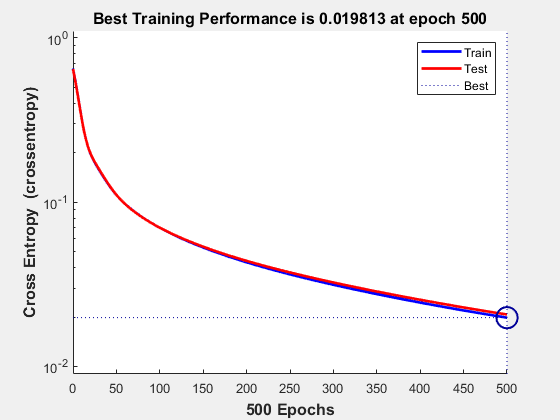

% Create a Pattern Recognition Network
net = patternnet(25, 'traingdm');

% Set up Division of Data for Training, Validation, Testing Subsets
net.divideParam.trainRatio = 80/100;
net.divideParam.valRatio = 0/100;
net.divideParam.testRatio = 20/100;

net.trainParam.epochs = 500;

% Train the Network
[net, tr] = train(net, featX, featY);
plotperform(tr)

% Test the Network with the test subset from the current dataset
tInd = tr.testInd;
tstOutputs = net(featX(:,tInd));
[c,~] = confusion(featY(:,tInd),tstOutputs);
fprintf("Classification error of test set: %f", c);

Classification error of test set: 0.006748

fprintf("Classification accuracy of test set: %f%%", 100*(1-c));

Classification accuracy of test set: 99.325236%

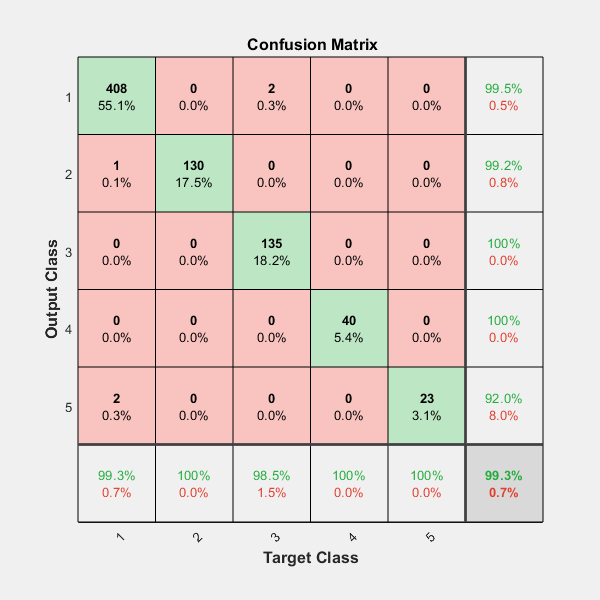

plotconfusion(featY(:,tInd),tstOutputs);

### SVM